# Apply component contribution method and analyse solution

## **Author: Ronan Fleming, Leiden University**

## **Reviewers: **

## INTRODUCTION

## PROCEDURE

## Configure the environment

All the installation instructions are in a separate .md file named vonBertalanffy.md in docs/source/installation

With all dependencies installed correctly, we configure our environment, verfy all dependencies, and add required fields and directories to the matlab path.

aPath = which('initVonBertalanffy');
basePath = strrep(aPath,'vonBertalanffy/initVonBertalanffy.m','');
addpath(genpath(basePath))
folderPattern=[filesep 'old'];
method = 'remove';
editCobraToolboxPath(basePath,folderPattern,method)

removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/directionalityReport/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/trainingModel/old


aPath = which('initVonBertalanffy');
basePath = strrep(aPath,'vonBertalanffy/initVonBertalanffy.m','');
addpath(genpath(basePath))
folderPattern=[filesep 'new'];
method = 'add';
editCobraToolboxPath(basePath,folderPattern,method)

adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/trainingModel/new


initVonBertalanffy

ChemAxon Marvin Beans is installed and working.
	linux-vdso.so.1 (0x00007ffd893da000)
	libc.so.6 => /lib/x86_64-linux-gnu/libc.so.6 (0x00007fe4c8028000)
	libopenbabel.so.5 => /usr/lib/libopenbabel.so.5 (0x00007fe4c7dd8000)
	libstdc++.so.6 => /usr/lib/x86_64-linux-gnu/libstdc++.so.6 (0x00007fe4c7bf7000)
	libgcc_s.so.1 => /usr/local/bin/MATLAB/R2021a/sys/os/glnxa64/libgcc_s.so.1 (0x00007fe4c79df000)
	/lib64/ld-linux-x86-64.so.2 (0x00007fe4c8247000)
	libdl.so.2 => /lib/x86_64-linux-gnu/libdl.so.2 (0x00007fe4c79d7000)
	libz.so.1 => /lib/x86_64-linux-gnu/libz.so.1 (0x00007fe4c79bb000)
	libm.so.6 => /lib/x86_64-linux-gnu/libm.so.6 (0x00007fe4c786c000)
	libgomp.so.1 => /usr/lib/x86_64-linux-gnu/libgomp.so.1 (0x00007fe4c782a000)
	libpthread.so.0 => /lib/x86_64-linux-gnu/libpthread.so.0 (0x00007fe4c7807000)

babel must depend on the system libstdc++.so.6 not the one from MATLAB
Trying to edit the 'LD_LIBRARY_PATH' to make sure that it has the correct system path before the Matlab path!
The solu

Load data input for component contribution method

load('data_prior_to_componentContribution')

Run component contribution method

 param.debug = 1;
 [model,solution] = componentContribution(model,combinedModel,param);

Running Component Contribution method


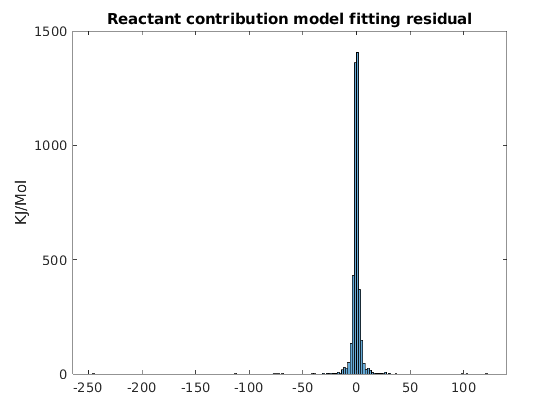

 figure;
 histogram(solution.e_rc)
 title('Reactant contribution model fitting residual')
 ylabel('KJ/Mol')

 [rcErrorSorted,rcSI]=sort(solution.e_rc);
 N=10;
 for i=1:N
     rxnFormula = printRxnFormula(combinedModel,'rxnAbbrList',combinedModel.rxns(rcSI(i)),'printFlag',0);
     fprintf('%g\t%s\t%s\n',solution.e_rc(rcSI(i)),combinedModel.rxns{rcSI(i)},rxnFormula{1});
 end

-245.117	TECRDB_695	C00089  -> C00031 
-112.088	TECRDB_2907	C00043 + C04688  -> C03688 + C04738 
-76.9602	TECRDB_4541	C00067 + C00101  -> C00143 
-74.9435	TECRDB_4540	C00067 + C00101  -> C00143 
-72.8151	TECRDB_4544	C00067 + C00101  -> C00143 
-69.7957	FORM_C00067	 -> C00067 
-40.0882	TECRDB_2906	C00043 + C04688  -> C03688 + C04738 
-39.1425	FORM_C00089	 -> C00089 
-31.6414	TECRDB_1919	C00002 + C01281  -> C00013 + C01299 
-31.4316	TECRDB_2520	C02115  -> C00067 + C00133 


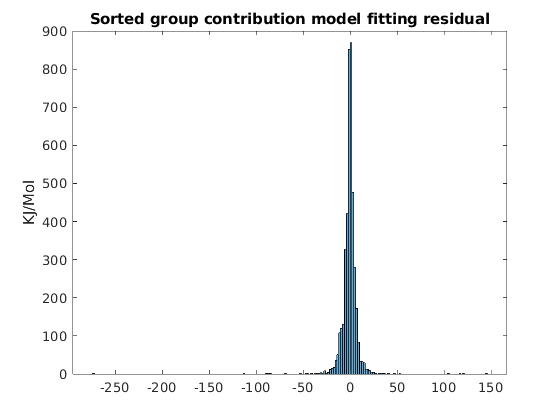

 [gcErrorSorted,gcSI]=sort(solution.e_gc);
 figure;
 histogram(solution.e_gc)
 title('Sorted group contribution model fitting residual')
 ylabel('KJ/Mol')

[gcErrorSorted,gcSI]=sort(solution.e_gc);
 N=10;
 for i=1:N
     rxnFormula = printRxnFormula(combinedModel,'rxnAbbrList',combinedModel.rxns(gcSI(i)),'printFlag',0);
     fprintf('%g\t%s\t%s\n',solution.e_gc(rcSI(i)),combinedModel.rxns{gcSI(i)},rxnFormula{1});
 end

-273.518	TECRDB_695	C00089  -> C00031 
-112.088	TECRDB_2907	C00043 + C04688  -> C03688 + C04738 
-89.1867	TECRDB_4541	C00067 + C00101  -> C00143 
-87.17	TECRDB_4540	C00067 + C00101  -> C00143 
-85.0417	TECRDB_4544	C00067 + C00101  -> C00143 
-45.0127	FORM_C06670	 -> C06670 
-40.0882	TECRDB_2719	C00026 + C00077  -> C00025 + C03912 
-10.9327	TECRDB_1833	C00001 + C00003 + C00449  -> C00004 + C00026 + C00047 
-31.6414	TECRDB_944	C03394  -> C00067 + C00111 
-27.767	FORM_C00067	 -> C00067 


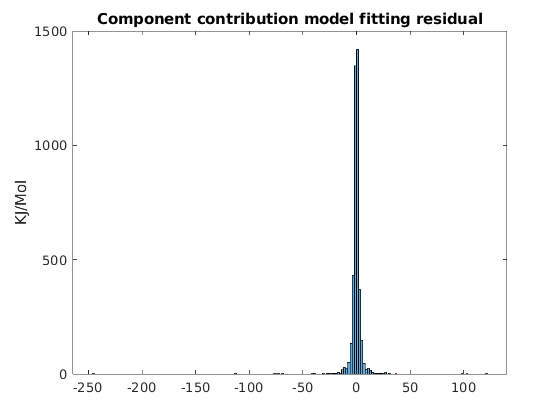

 figure;
 histogram(solution.e_cc)
 title('Component contribution model fitting residual')
 ylabel('KJ/Mol')

 [rcErrorSorted,ccSI]=sort(solution.e_cc);
 N=10;
 for i=1:N
     rxnFormula = printRxnFormula(combinedModel,'rxnAbbrList',combinedModel.rxns(ccSI(i)),'printFlag',0);
     fprintf('%g\t%s\t%s\n',solution.e_cc(rcSI(i)),combinedModel.rxns{ccSI(i)},rxnFormula{1});
 end

-245.117	TECRDB_695	C00089  -> C00031 
-112.088	TECRDB_2907	C00043 + C04688  -> C03688 + C04738 
-76.9602	TECRDB_4541	C00067 + C00101  -> C00143 
-74.9435	TECRDB_4540	C00067 + C00101  -> C00143 
-72.8151	TECRDB_4544	C00067 + C00101  -> C00143 
-69.7957	FORM_C00067	 -> C00067 
-40.0882	TECRDB_2906	C00043 + C04688  -> C03688 + C04738 
-39.1425	FORM_C00089	 -> C00089 
-31.6414	TECRDB_1919	C00002 + C01281  -> C00013 + C01299 
-31.4316	TECRDB_2520	C02115  -> C00067 + C00133 


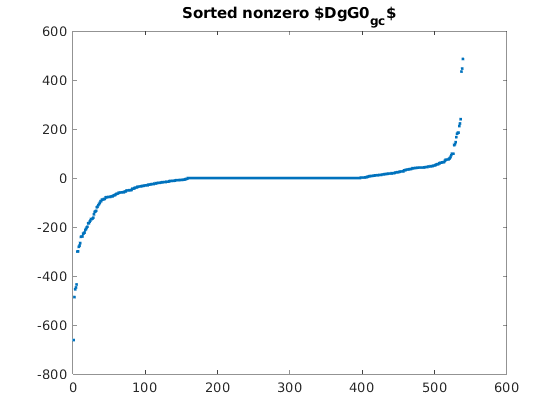

DgG0_gc = solution.DgG0_gc(solution.DgG0_gc~=0);
 DgG0_gc_sorted = sort(DgG0_gc);
 figure;
 plot(DgG0_gc_sorted,'.')
 title('Sorted nonzero $DgG0_{gc}$')